% Set the length of the SSH chain (2N)
N = 40;  % Chain length is 2N, here N = 20
delta = -0.7;

delta = -0.7000

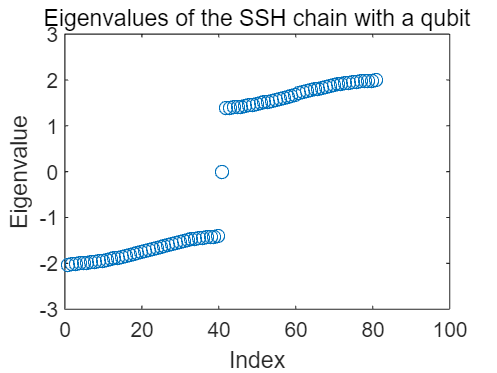

t1 = 1 - delta;  % Intracell coupling
t2 = 1 + delta;  % Intercell coupling
gamma = 0.6;  % Coupling strength between the qubit and the SSH chain

% Create the Hamiltonian matrix
H = zeros(2*N + 1);  % Include additional state for the qubit
for i = 1:2*N-1
    if mod(i,2) == 1
        H(i,i+1) = t1;
        H(i+1,i) = t1;
    else
        H(i,i+1) = t2;
        H(i+1,i) = t2;
    end
end

% Coupling the qubit to the left end of the SSH chain
H(N, 2*N+1) = gamma;
H(2*N+1, N) = gamma;

% Compute eigenvalues and eigenvectors
[eigenvectors, eigenvalues_matrix] = eig(H);
eigenvalues = diag(eigenvalues_matrix);

% Plot all eigenvalues
figure;
plot(1:2*N+1, eigenvalues, 'o');
title('Eigenvalues of the SSH chain with a qubit');
xlabel('Index');
ylabel('Eigenvalue');

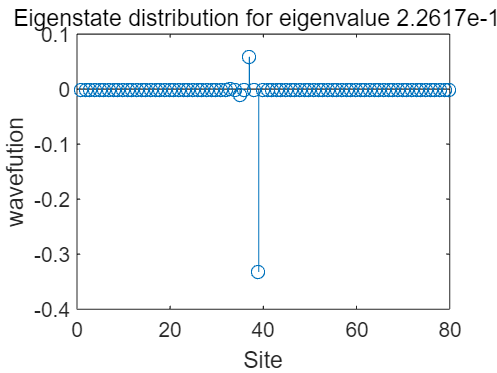


% Select an eigenvalue and its corresponding eigenvector
% Here we select the first eigenvalue's corresponding eigenvector
chosen_index = N + 1;
chosen_eigenvector = eigenvectors(1:2*N, chosen_index);

% Plot the distribution of the eigenvector
figure;
stem(chosen_eigenvector);
title(['Eigenstate distribution for eigenvalue ', num2str(eigenvalues(chosen_index))]);
xlabel('Site');
ylabel('wavefution');